T1=10;T2=4;T3=1; Ts=0.2; %[sec]
A=2;

Wp= tf(A, conv(conv([T1 1],[T2 1]),[T3 1]));

Dp=c2d(Wp,Ts,'zoh')

Dp =
 
  6.235e-05 z^2 + 0.0002333 z + 5.448e-05
  ---------------------------------------
     z^3 - 2.75 z^2 + 2.514 z - 0.7634
 
Sample time: 0.2 seconds
Discrete-time transfer function.



pzmap(Dp);
roots(Dp.Denominator{1})

ans =     0.9802
    0.9512
    0.8187



megold=exp((3*1i)*Ts)

megold = 0.8253 + 0.5646i

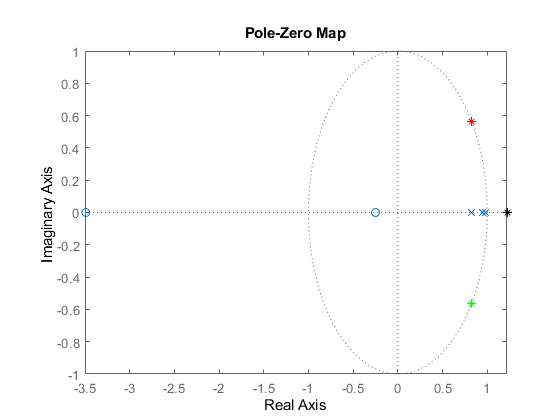

hold on; plot(megold, 'r*');
hold on; plot(conj(megold), 'g*');
hold on; plot(exp(1*Ts),0, 'k*');

D1=tf(1,[1 -0.5], Ts);
W1=d2c(D1, 'zoh')

W1 =
 
    6.931
  ---------
  s + 3.466
 
Continuous-time transfer function.



D2=tf(1, [1 0.1], Ts);
W2=d2c(D2, 'zoh')

W2 =
 
     10.47 s + 344.8
  ---------------------
  s^2 + 23.03 s + 379.3
 
Continuous-time transfer function.



roots(W2.Denominator{1})

ans =  -11.5129 +15.7080i
 -11.5129 -15.7080i


wN = pi/Ts

wN = 15.7080

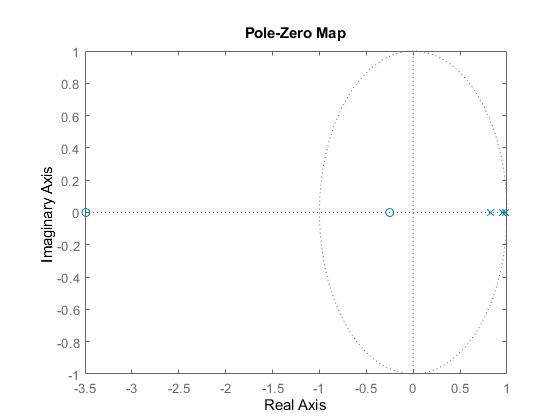

clear;clc; hold off;

T1=10;T2=4;T3=1; Ts=0.2; %[sec]
A=2;

Wp= tf(A, conv(conv([T1 1],[T2 1]),[T3 1]));

Dp=c2d(Wp,Ts,'zoh')

Dp =
 
  6.235e-05 z^2 + 0.0002333 z + 5.448e-05
  ---------------------------------------
     z^3 - 2.75 z^2 + 2.514 z - 0.7634
 
Sample time: 0.2 seconds
Discrete-time transfer function.



Wp

Wp =
 
              2
  --------------------------
  40 s^3 + 54 s^2 + 15 s + 1
 
Continuous-time transfer function.



Dp

Dp =
 
  6.235e-05 z^2 + 0.0002333 z + 5.448e-05
  ---------------------------------------
     z^3 - 2.75 z^2 + 2.514 z - 0.7634
 
Sample time: 0.2 seconds
Discrete-time transfer function.



pzmap(Dp);

B=Dp.Numerator{1}

B = 	1.0e+-3 *

         0    0.0624    0.2333    0.0545


B=B(2:end); %leszedjuk a vezeto nullat

roots(B)

ans =    -3.4910
   -0.2503


%Nem tudom betenni, az egyik instabil, mig a masik a PACMAN
%szajaban van

w0=5/(T1+T2+T3);
xi=0.7;
s1=-w0*xi+j*w0*sqrt(1-xi^2);
s2=conj(s1);
scinf=-3*w0;
soinf=-5*w0;

4*pi/180/w0 %mintaveteli ido

ans = 0.2094

Ts %majdnem ennyi

Ts = 0.2000


grB=length(B)-1 % fokszama B-nek

grB = 2

grA=length(Dp.Denominator{1})-1

grA = 3

R1v = [1.0000 -1.1300 0.3638];
S = [83.1497 -226.3095 204.9084 -61.6985];
T = [2.1962 -4.7209 3.3826 -0.8079];
R = conv(R1v, [1 -1]);